init = sortrows(Monte(100, 0.002, [0.03, 0.25, 0.25], [0.06, 0.4, 0.4], 0.0351), 4)

init = init(1:10, 1:3);
init2 = sortrows(Monte(100, 0.002, min(init), max(init), 0.0351), 4)

init2 = init2(1:5, 1:3);
init3 = sortrows(Monte(100, 0.002, min(init2), max(init2), 0.0351), 4)

init3 = init3(1:5, 1:3);
init4 = sortrows(Monte(100, 0.003, min(init3), max(init3), 0.0351), 4)

init4 = init4(1:5, 1:3);
init5 = sortrows(Monte(100, 0.003, min(init4), max(init4), 0.0351), 4)

init5 = init5(1:5, 1:3);
init6 = sortrows(Monte(100, 0.003, min(init5), max(init5), 0.0351), 4)

init6 = init6(1:5, 1:3);
init7 = sortrows(Monte(100, 0.003, min(init6), max(init6), 0.0351), 4)

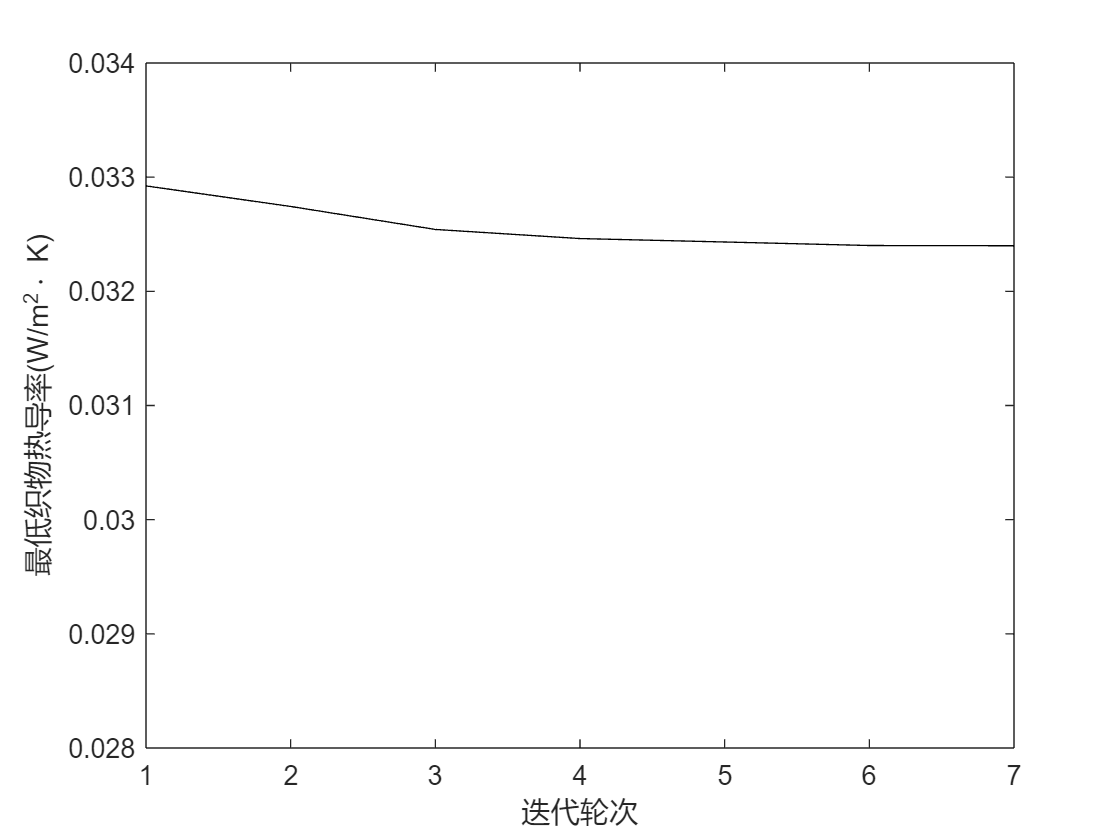

result = [
    init(1,:), 0.0329235; 
    init2(1,:),0.032743341; 
    init3(1,:),0.03254212; 
    init4(1,:), 0.032462324; 
    init5(1,:), 0.032432191; 
    init6(1,:),0.0324013; 
    init7(1,:)];

plot(1:7, result(:,4),'-k')
xlabel("迭代轮次")
ylabel("最低织物热导率(W/m^2\cdot K)")
ylim([0.028, 0.034])

lat = zeros(1,7);
lon = zeros(1,7);
for i=1:7
    a_1 = result(i,2)/2;
    a_2 = result(i,3)/2;
    d = result(i,1)/2;
    coefficients_1 = [3*d^2, 2*a_1*d, 4*d^2 - a_1^2];
    coefficients_2 = [3*d^2, 2*a_2*d, 4*d^2 - a_2^2];
    a = rad2deg(-1/atan(roots(coefficients_1)));
    lat(i) = a(1);
    b = rad2deg(-1/atan(roots(coefficients_2)));
    lon(i) = b(1);
end

1./result(:,3)*200

ans =   578.7294
  766.5020
  715.4421
  741.1077
  733.4399
  741.2980
  741.1254
